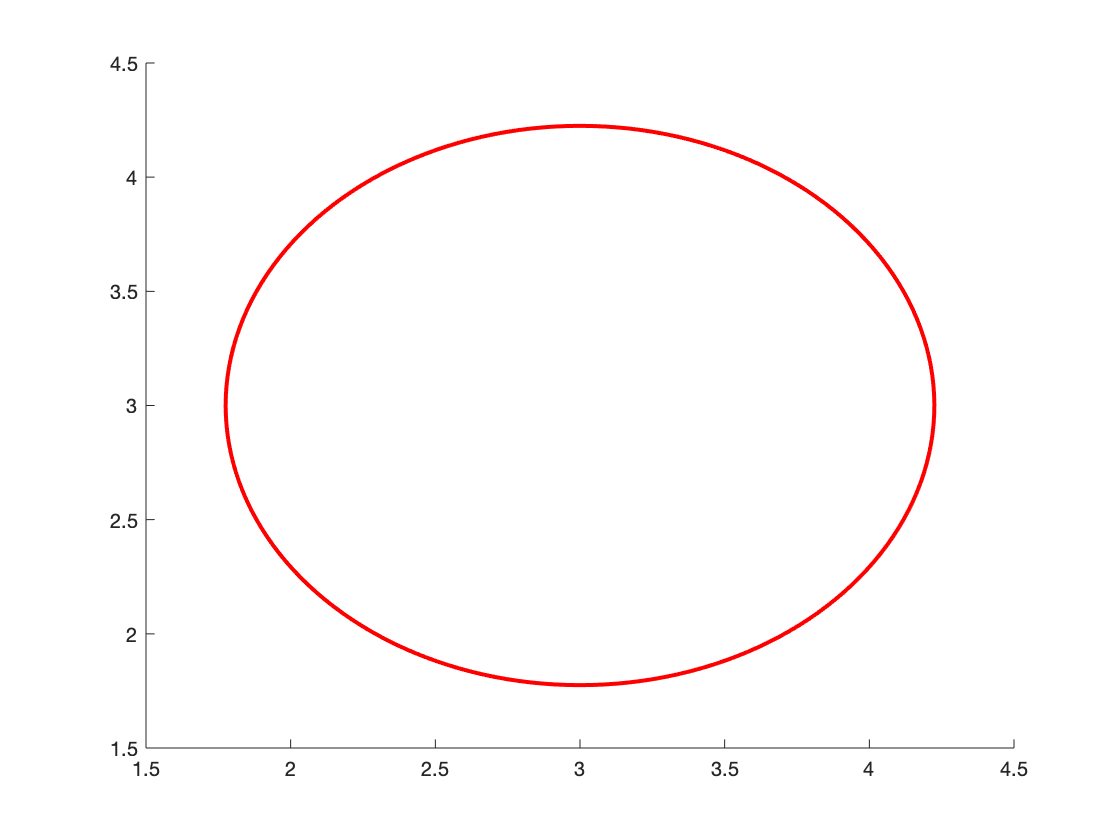

viscircles([3,3], sqrt(1.5));

% C_3
syms x1 x2 x3
f = (x3 - 3)^2 - (x1 + 2*x2 - 13)^3 - 10

$$f = {\left(x_{3}-3\right)}^{2}-{\left(x_{1}+2\,x_{2}-13\right)}^{3}-10$$


H = hessian(f)

$$H = \left(\begin{array}{ccc} 78-12\,x_{2}-6\,x_{1} & 156-24\,x_{2}-12\,x_{1} & 0\\ 156-24\,x_{2}-12\,x_{1} & 312-48\,x_{2}-24\,x_{1} & 0\\ 0 & 0 & 2 \end{array}\right)$$

syms r
H = subs(H, x1 + 2*x2 - 13, r)

$$H = \left(\begin{array}{ccc} -6\,r & -12\,r & 0\\ -12\,r & -24\,r & 0\\ 0 & 0 & 2 \end{array}\right)$$

det(H(1:1, 1:1))

$$ans = -6\,r$$

det(H(1:2, 1:2))

$$ans = 0$$

det(H)

$$ans = 0$$

syms d1 d2 d3
[d1 d2 d3] * H * [d1;d2;d3]

$$ans = 2\,{d_{3}}^{2}-d_{1}\,\left(6\,d_{1}\,r+12\,d_{2}\,r\right)-d_{2}\,\left(12\,d_{1}\,r+24\,d_{2}\,r\right)$$

expand(ans)

$$ans = -6\,r\,{d_{1}}^{2}-24\,r\,d_{1}\,d_{2}-24\,r\,{d_{2}}^{2}+2\,{d_{3}}^{2}$$